clc;
clear all;
warning off;
%     A1     b1      A2      b2      A5      b5      Tp      Tf     Tvl
%     Tv0    yita    S1      S2      S3      S4      k0      k1     k2      k3
lb = [
      0       %S1
      0       %S2
      0       %S3
      0       %S4
     ]; 

ub = [
      20       %S1
      20       %S2
      20       %S3
      20       %S4
     ];    

Npara = length(lb); 

S1 = 2;S2 = 5;
S3 = 2;S4 = 5;

para_init = [S1,S2,S3,S4];

%% ==================== 1. 工况设置 ============================
meanangle    = 9.6;
averageangle = 7;
conditions   = input_condition(meanangle,averageangle);
airfoildata  = input_afdata;

CFDdatapath = 're1e6_9.6_f0.6.txt';

%% ==================== 2. 整理变量 ============================
setcase.meanangle    = meanangle;
setcase.averageangle = averageangle;
setcase.conditions   = conditions;
setcase.airfoldata   = airfoildata;
setcase.CFDdatapath  = CFDdatapath;

para_local_GZ = run_optimal_GZ(para_init,Npara,lb,ub,setcase);

===== 动态失速BL模型参数优化开始【CFD拟合+面积相似度】 =====

单目标优化:
4 变量
1 非线性不等式约束

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible
正在使用 'Processes' 配置文件启动并行池(parpool)...
已连接到具有 16 个工作进程的并行池。

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1          12675      0.651375            0      0
    2          25094      0.651373            0      0
    3          37513      0.651373            0      0
优化结束: 适应度值的平均变化小于 options.FunctionTolerance 且约束违反值小于 options.ConstraintTolerance。
===== 优化完成！最优适应度值 = 0.65137326 =====

==================== 原始参数 ↔ 优化后最优参数 对比表 ====================
原始适应度=0.070380 | 优化适应度=0.081601
   S1 : 原始值=2.000000 | 优化值=9.751887
   S2 : 原始值=5.000000 | 优化值=3.123704
   S3 : 原始值=2.000000 | 优化值=15.431832
   S4 : 原始值=5.000000 | 优化值=12.127544

优化结果已保存至：Boundary_layer_fitness.mat
历时 118.321869 秒。


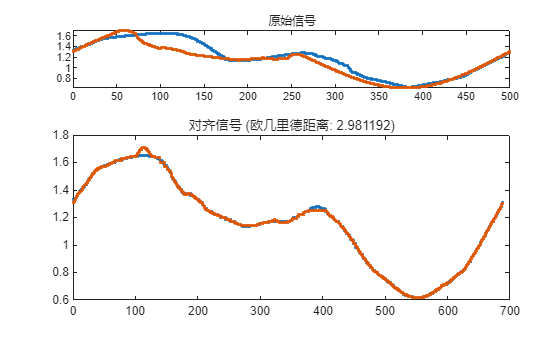

ans = 2.9812

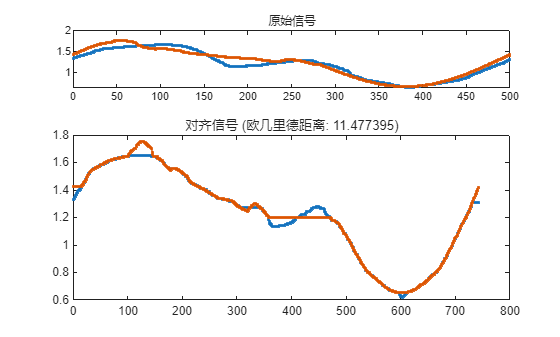

ans = 11.4774

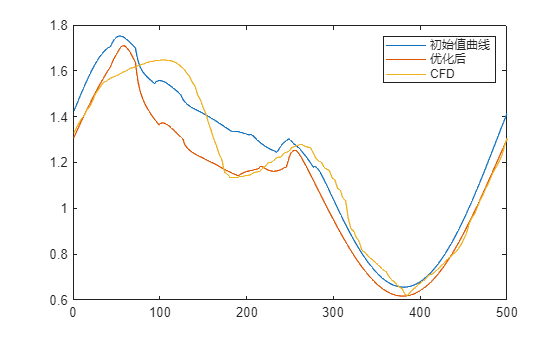

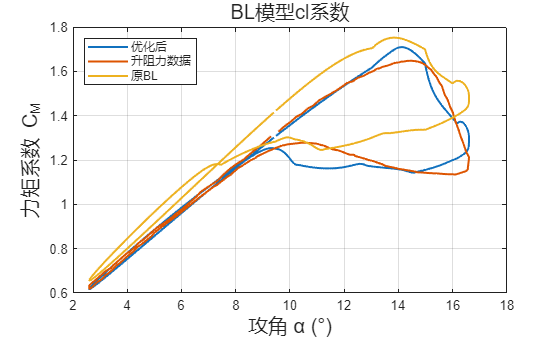

compare_optimal_result_GZ(para_local_GZ,para_init,setcase);